# GP-UKF on Orbit ver. (GP-UKFとUKFを同時に回してcompareする)

軌道運動考慮

GPUKFの入力にmApp_pastMean を追加

Order of running codes

- mainAtti_onOrbit.mlx: generate true values

- genTrainStaticPastMean_onOrbit.mlx: generate training data

- mainGP_staticPastMean_onOrbit.mlx: training step for the GP

- This code: estimate attitude by GPUKF and UKF respectively and compare them

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../../gpryui/'));

% create directory
% mkdir ../results/GPUKF_staticFixed/

tStart = tic;

### constants

% inputGP = "attitude"
% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean"
inputGP = "attitude, relativePosition, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"



earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = "boxWing"; % flatPlate or boxWing
trainMethod = "_lcAtti_onOrbit";

observation = 'mag'; % light curve magnitude or its inverse value

tSpanPast = 20;


% random number generator
rng(2022, 'twister');

### load true value and set noise

onjName_lcAtti_static.mat = ['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'satPos', 'obsPos', 'sunPos']

% load true value
fName = strcat(model, trainMethod, ".mat")

fName = "boxWing_lcAtti_onOrbit.mat"

trueData = load(fName); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

r_true_max = max(trueData.r, [], "all");
obsECI_true_max = max(trueData.obsECI, [], "all");
obsToTarget_max = max(trueData.r - trueData.obsECI, [], "all");


sat_true = trueData.sat; % 真値の表面特性
sat_u = trueData.sat; 
% UKFに用いる表面特性 
sat_u.Ca = 0.0;
sat_u.Cd = 0.5; % AS model の rho
sat_u.Cs = 1.0 - (sat_u.Ca + sat_u.Cs);
% sat_u.Cs = 0.5;

t_ = trueData.t_;
tn_ = size(t_, 1);

% set noise
sigTrue = 0.05;
% sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF parameters

わからん

n_ = 3; % # of state variable := [error GRP] or [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;% わからん
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね？

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

% for GP-UKF
xEst_gu = zeros(tn_, n_); % := [error GRP]
Pdiag_gu = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_gu = zeros(tn_, 4);
wGlobal_gu = zeros(tn_, 3);
mApp_pastMean = zeros(tn_, 1);
% for UKF
xEst_u = zeros(tn_, n_); % := [error GRP]
Pdiag_u = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_u = zeros(tn_, 4);
wGlobal_u = zeros(tn_, 3);


ye_gu = zeros(tn_, 1); % GPUKFの予測値
ye_lc_gpAtti = zeros(tn_, 1); % GPUKFの姿勢に対してlc modelを用いた予測値 (for GP modelの精度確認)
ye_u = zeros(tn_, 1); % UKfの予測値

ye0 = 0; % わからん→sigma pointの中心？
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = trueData.mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude), gaussian distribution
obsRel = trueData.obsECI - trueData.r;
dTmp = vecnorm(obsRel, 2, 2); % [m], distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal_gu(1,:) = trueData.q(1,:); % true initial
qGlobal_u(1,:) = trueData.q(1,:); % true initial
% wGlobal_gu(1,:) = trueData.w(1,:); % true initial
mApp_pastMean(1,1) = trueData.mApp(1,1); % とりあえず真値の初期値をmApp_pastMeanの初期推定値として使う

% large initial error 
iniErr = deg2rad(90);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));

% small initial error
iniErr_q = deg2rad([-10, 5, -10]); % zyx表記
% iniErr_w = deg2rad([1, 1, 1]); % [rad/s]

qGlobal_gu(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
qGlobal_u(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
% wGlobal(1,:) = wGlobal(1,:) + [iniErr_w(1), iniErr_w(2), iniErr_w(3)];

#### initial covariance for 3$\sigma
$ bound

Pdiag_gu(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% Pdiag_gu(1,:) = (iniErr_q ./ 3).^2;
Pdiag_u(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% p(1,:) = ([iniErr_q, iniErr_w] ./ 3).^2;
Pcov_gu = diag(Pdiag_gu(1,:));
Pcov_u = diag(Pdiag_u(1,:));

% x:= [error GRP, angular rate]
xEst_gu(1,:) = zeros(1, n_); % わからん→誤差GRPは毎回0にする．？
xEst_u(1,:) = zeros(1, n_);

#### initial obsevation step

load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
if strcmp(inputGP, "attitude, position, mApp_pastMean") % こっちの入力おかしいかも
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:), trueData.r(1,:)./r_true_max, trueData.obsECI(1,:)./obsECI_true_max, mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do); 
elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:), (trueData.r(1,:)-trueData.obsECI(1,:))./obsToTarget_max, mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do);
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:),mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do);
elseif strcmp(inputGP, "attitude")
    [ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:)], x_train, y_train, params, Kinv_Do);
end    
ye_gu(1,1) = ye_gu(1,1) + y_train_mean(1,1);

nu = 1; % sunlit?, earth shadowing?
ye_lc_gpAtti(1,1) = lc(sat_true, 4, qGlobal_gu(1,:), trueData.r(1,:), trueData.obsECI(1,:), trueData.sunPosI(1,:), nu, 'AS'); % 初期予測観測値

ye_u(1,1) = lc(sat_u, 4, qGlobal_u(1,:), trueData.r(1,:), trueData.obsECI(1,:), trueData.sunPosI(1,:), nu, 'AS');

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

### GP-UKF

% load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
% filter = "GPUKF" % "GPUKF" or "UKF"

tStart_GPUKF_UKF = tic

tStart_GPUKF_UKF = uint64
2069847292947

for i = 1:tn_-1
    ti_GPUKF = tic;
    
    dt_ = t_(i+1) - t_(i);
    [qGlobal_gu(i+1, :), wGlobal_gu(i+1, :), Pcov_gu, Pdiag_gu(i+1,:), qGlobal_u(i+1,:), wGlobal_u(i+1,:), Pcov_u, Pdiag_u(i+1,:), ye_gu(i+1,1), ye_lc_gpAtti(i+1,1), ye_u(i+1,1), mApp_pastMean(i+1)] = lcGPUKF_cmp_staticPastMean_onOrbit(dt_, xEst_gu(i, :), xEst_u(i,:), Pcov_gu, Pcov_u, mAppNoise(i), mAppNoise(i+1), ye_gu(i), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal_gu(i, :), qGlobal_u(i,:), trueData.w(i,:), trueData.r(i+1,:), trueData.obsECI(i+1,:), trueData.sunPosI(i+1,:), mApp_pastMean(i,1), sat_true, sat_u, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do, trueData.jdHistory(i), tSpanPast, inputGP, r_true_max, obsECI_true_max, obsToTarget_max);

    fprintf("the number of the time step i: %d \n", i);
    fprintf("the calculation time to go forward to the next step: %f [min] \n", toc(ti_GPUKF)/60);
    % [qGlobal(i+1, :), wGlobal(i+1, :), Pcov] = lcGPUKF_staticFixed(dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
    %     ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), wGlobal(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), trueData.sat, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);
end

the number of the time step i: 1 


the calculation time to go forward to the next step: 0.002902 [min] 


the number of the time step i: 2 


the calculation time to go forward to the next step: 0.001771 [min] 


the number of the time step i: 3 


the calculation time to go forward to the next step: 0.001721 [min] 


the number of the time step i: 4 


the calculation time to go forward to the next step: 0.001595 [min] 


the number of the time step i: 5 


the calculation time to go forward to the next step: 0.001614 [min] 


the number of the time step i: 6 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 7 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 8 


the calculation time to go forward to the next step: 0.001733 [min] 


the number of the time step i: 9 


the calculation time to go forward to the next step: 0.001885 [min] 


the number of the time step i: 10 


the calculation time to go forward to the next step: 0.001601 [min] 


the number of the time step i: 11 


the calculation time to go forward to the next step: 0.001530 [min] 


the number of the time step i: 12 


the calculation time to go forward to the next step: 0.001574 [min] 


the number of the time step i: 13 


the calculation time to go forward to the next step: 0.001620 [min] 


the number of the time step i: 14 


the calculation time to go forward to the next step: 0.002116 [min] 


the number of the time step i: 15 


the calculation time to go forward to the next step: 0.002634 [min] 


the number of the time step i: 16 


the calculation time to go forward to the next step: 0.001675 [min] 


the number of the time step i: 17 


the calculation time to go forward to the next step: 0.001588 [min] 


the number of the time step i: 18 


the calculation time to go forward to the next step: 0.001534 [min] 


the number of the time step i: 19 


the calculation time to go forward to the next step: 0.001627 [min] 


the number of the time step i: 20 


the calculation time to go forward to the next step: 0.001723 [min] 


the number of the time step i: 21 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 22 


the calculation time to go forward to the next step: 0.001600 [min] 


the number of the time step i: 23 


the calculation time to go forward to the next step: 0.001593 [min] 


the number of the time step i: 24 


the calculation time to go forward to the next step: 0.001877 [min] 


the number of the time step i: 25 


the calculation time to go forward to the next step: 0.001833 [min] 


the number of the time step i: 26 


the calculation time to go forward to the next step: 0.001589 [min] 


the number of the time step i: 27 


the calculation time to go forward to the next step: 0.001554 [min] 


the number of the time step i: 28 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 29 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 30 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 31 


the calculation time to go forward to the next step: 0.001652 [min] 


the number of the time step i: 32 


the calculation time to go forward to the next step: 0.001655 [min] 


the number of the time step i: 33 


the calculation time to go forward to the next step: 0.001575 [min] 


the number of the time step i: 34 


the calculation time to go forward to the next step: 0.001618 [min] 


the number of the time step i: 35 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 36 


the calculation time to go forward to the next step: 0.002624 [min] 


the number of the time step i: 37 


the calculation time to go forward to the next step: 0.002803 [min] 


the number of the time step i: 38 


the calculation time to go forward to the next step: 0.001522 [min] 


the number of the time step i: 39 


the calculation time to go forward to the next step: 0.001476 [min] 


the number of the time step i: 40 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 41 


the calculation time to go forward to the next step: 0.001546 [min] 


the number of the time step i: 42 


the calculation time to go forward to the next step: 0.001535 [min] 


the number of the time step i: 43 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 44 


the calculation time to go forward to the next step: 0.001812 [min] 


the number of the time step i: 45 


the calculation time to go forward to the next step: 0.001555 [min] 


the number of the time step i: 46 


the calculation time to go forward to the next step: 0.001572 [min] 


the number of the time step i: 47 


the calculation time to go forward to the next step: 0.001591 [min] 


the number of the time step i: 48 


the calculation time to go forward to the next step: 0.001556 [min] 


the number of the time step i: 49 


the calculation time to go forward to the next step: 0.001550 [min] 


the number of the time step i: 50 


the calculation time to go forward to the next step: 0.001903 [min] 


the number of the time step i: 51 


the calculation time to go forward to the next step: 0.001605 [min] 


the number of the time step i: 52 


the calculation time to go forward to the next step: 0.001595 [min] 


the number of the time step i: 53 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 54 


the calculation time to go forward to the next step: 0.001558 [min] 


the number of the time step i: 55 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 56 


the calculation time to go forward to the next step: 0.001894 [min] 


the number of the time step i: 57 


the calculation time to go forward to the next step: 0.001601 [min] 


the number of the time step i: 58 


the calculation time to go forward to the next step: 0.002631 [min] 


the number of the time step i: 59 


the calculation time to go forward to the next step: 0.002002 [min] 


the number of the time step i: 60 


the calculation time to go forward to the next step: 0.001571 [min] 


the number of the time step i: 61 


the calculation time to go forward to the next step: 0.001594 [min] 


the number of the time step i: 62 


the calculation time to go forward to the next step: 0.001832 [min] 


the number of the time step i: 63 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 64 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 65 


the calculation time to go forward to the next step: 0.001575 [min] 


the number of the time step i: 66 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 67 


the calculation time to go forward to the next step: 0.001559 [min] 


the number of the time step i: 68 


the calculation time to go forward to the next step: 0.001752 [min] 


the number of the time step i: 69 


the calculation time to go forward to the next step: 0.001583 [min] 


the number of the time step i: 70 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 71 


the calculation time to go forward to the next step: 0.001543 [min] 


the number of the time step i: 72 


the calculation time to go forward to the next step: 0.001798 [min] 


the number of the time step i: 73 


the calculation time to go forward to the next step: 0.001933 [min] 


the number of the time step i: 74 


the calculation time to go forward to the next step: 0.001645 [min] 


the number of the time step i: 75 


the calculation time to go forward to the next step: 0.001563 [min] 


the number of the time step i: 76 


the calculation time to go forward to the next step: 0.001557 [min] 


the number of the time step i: 77 


the calculation time to go forward to the next step: 0.001529 [min] 


the number of the time step i: 78 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 79 


the calculation time to go forward to the next step: 0.002439 [min] 


the number of the time step i: 80 


the calculation time to go forward to the next step: 0.002649 [min] 


the number of the time step i: 81 


the calculation time to go forward to the next step: 0.001596 [min] 


the number of the time step i: 82 


the calculation time to go forward to the next step: 0.001565 [min] 


the number of the time step i: 83 


the calculation time to go forward to the next step: 0.001649 [min] 


the number of the time step i: 84 


the calculation time to go forward to the next step: 0.001961 [min] 


the number of the time step i: 85 


the calculation time to go forward to the next step: 0.001747 [min] 


the number of the time step i: 86 


the calculation time to go forward to the next step: 0.001657 [min] 


the number of the time step i: 87 


the calculation time to go forward to the next step: 0.001703 [min] 


the number of the time step i: 88 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 89 


the calculation time to go forward to the next step: 0.001727 [min] 


the number of the time step i: 90 


the calculation time to go forward to the next step: 0.001764 [min] 


the number of the time step i: 91 


the calculation time to go forward to the next step: 0.001607 [min] 


the number of the time step i: 92 


the calculation time to go forward to the next step: 0.001507 [min] 


the number of the time step i: 93 


the calculation time to go forward to the next step: 0.001547 [min] 


the number of the time step i: 94 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 95 


the calculation time to go forward to the next step: 0.001618 [min] 


the number of the time step i: 96 


the calculation time to go forward to the next step: 0.001608 [min] 


the number of the time step i: 97 


the calculation time to go forward to the next step: 0.001552 [min] 


the number of the time step i: 98 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 99 


the calculation time to go forward to the next step: 0.001507 [min] 


the number of the time step i: 100 


the calculation time to go forward to the next step: 0.001552 [min] 


the number of the time step i: 101 


the calculation time to go forward to the next step: 0.002553 [min] 


the number of the time step i: 102 


the calculation time to go forward to the next step: 0.001970 [min] 


the number of the time step i: 103 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 104 


the calculation time to go forward to the next step: 0.001527 [min] 


the number of the time step i: 105 


the calculation time to go forward to the next step: 0.001616 [min] 


the number of the time step i: 106 


the calculation time to go forward to the next step: 0.001613 [min] 


the number of the time step i: 107 


the calculation time to go forward to the next step: 0.001611 [min] 


the number of the time step i: 108 


the calculation time to go forward to the next step: 0.001627 [min] 


the number of the time step i: 109 


the calculation time to go forward to the next step: 0.001554 [min] 


the number of the time step i: 110 


the calculation time to go forward to the next step: 0.001552 [min] 


the number of the time step i: 111 


the calculation time to go forward to the next step: 0.001567 [min] 


the number of the time step i: 112 


the calculation time to go forward to the next step: 0.001508 [min] 


the number of the time step i: 113 


the calculation time to go forward to the next step: 0.001541 [min] 


the number of the time step i: 114 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 115 


the calculation time to go forward to the next step: 0.001736 [min] 


the number of the time step i: 116 


the calculation time to go forward to the next step: 0.001591 [min] 


the number of the time step i: 117 


the calculation time to go forward to the next step: 0.001500 [min] 


the number of the time step i: 118 


the calculation time to go forward to the next step: 0.001568 [min] 


the number of the time step i: 119 


the calculation time to go forward to the next step: 0.001599 [min] 


the number of the time step i: 120 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 121 


the calculation time to go forward to the next step: 0.001736 [min] 


the number of the time step i: 122 


the calculation time to go forward to the next step: 0.001599 [min] 


the number of the time step i: 123 


the calculation time to go forward to the next step: 0.002079 [min] 


the number of the time step i: 124 


the calculation time to go forward to the next step: 0.002300 [min] 


the number of the time step i: 125 


the calculation time to go forward to the next step: 0.001578 [min] 


the number of the time step i: 126 


the calculation time to go forward to the next step: 0.001499 [min] 


the number of the time step i: 127 


the calculation time to go forward to the next step: 0.001785 [min] 


the number of the time step i: 128 


the calculation time to go forward to the next step: 0.001556 [min] 


the number of the time step i: 129 


the calculation time to go forward to the next step: 0.001521 [min] 


the number of the time step i: 130 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 131 


the calculation time to go forward to the next step: 0.001519 [min] 


the number of the time step i: 132 


the calculation time to go forward to the next step: 0.001992 [min] 


the number of the time step i: 133 


the calculation time to go forward to the next step: 0.001579 [min] 


the number of the time step i: 134 


the calculation time to go forward to the next step: 0.001515 [min] 


the number of the time step i: 135 


the calculation time to go forward to the next step: 0.001551 [min] 


the number of the time step i: 136 


the calculation time to go forward to the next step: 0.001631 [min] 


the number of the time step i: 137 


the calculation time to go forward to the next step: 0.001507 [min] 


the number of the time step i: 138 


the calculation time to go forward to the next step: 0.001783 [min] 


the number of the time step i: 139 


the calculation time to go forward to the next step: 0.001622 [min] 


the number of the time step i: 140 


the calculation time to go forward to the next step: 0.001536 [min] 


the number of the time step i: 141 


the calculation time to go forward to the next step: 0.001592 [min] 


the number of the time step i: 142 


the calculation time to go forward to the next step: 0.001554 [min] 


the number of the time step i: 143 


the calculation time to go forward to the next step: 0.001529 [min] 


the number of the time step i: 144 


the calculation time to go forward to the next step: 0.001586 [min] 


the number of the time step i: 145 


the calculation time to go forward to the next step: 0.002347 [min] 


the number of the time step i: 146 


the calculation time to go forward to the next step: 0.002177 [min] 


the number of the time step i: 147 


the calculation time to go forward to the next step: 0.001518 [min] 


the number of the time step i: 148 


the calculation time to go forward to the next step: 0.001570 [min] 


the number of the time step i: 149 


the calculation time to go forward to the next step: 0.001590 [min] 


the number of the time step i: 150 


the calculation time to go forward to the next step: 0.001802 [min] 


the number of the time step i: 151 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 152 


the calculation time to go forward to the next step: 0.001473 [min] 


the number of the time step i: 153 


the calculation time to go forward to the next step: 0.001558 [min] 


the number of the time step i: 154 


the calculation time to go forward to the next step: 0.001513 [min] 


the number of the time step i: 155 


the calculation time to go forward to the next step: 0.001555 [min] 


the number of the time step i: 156 


the calculation time to go forward to the next step: 0.001491 [min] 


the number of the time step i: 157 


the calculation time to go forward to the next step: 0.001843 [min] 


the number of the time step i: 158 


the calculation time to go forward to the next step: 0.001583 [min] 


the number of the time step i: 159 


the calculation time to go forward to the next step: 0.001537 [min] 


the number of the time step i: 160 


the calculation time to go forward to the next step: 0.001532 [min] 


the number of the time step i: 161 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 162 


the calculation time to go forward to the next step: 0.001754 [min] 


the number of the time step i: 163 


the calculation time to go forward to the next step: 0.002005 [min] 


the number of the time step i: 164 


the calculation time to go forward to the next step: 0.001588 [min] 


the number of the time step i: 165 


the calculation time to go forward to the next step: 0.001510 [min] 


the number of the time step i: 166 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 167 


the calculation time to go forward to the next step: 0.002371 [min] 


the number of the time step i: 168 


the calculation time to go forward to the next step: 0.002614 [min] 


the number of the time step i: 169 


the calculation time to go forward to the next step: 0.001589 [min] 


the number of the time step i: 170 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 171 


the calculation time to go forward to the next step: 0.001572 [min] 


the number of the time step i: 172 


the calculation time to go forward to the next step: 0.001555 [min] 


the number of the time step i: 173 


the calculation time to go forward to the next step: 0.001521 [min] 


the number of the time step i: 174 


the calculation time to go forward to the next step: 0.001884 [min] 


the number of the time step i: 175 


the calculation time to go forward to the next step: 0.001547 [min] 


the number of the time step i: 176 


the calculation time to go forward to the next step: 0.001500 [min] 


the number of the time step i: 177 


the calculation time to go forward to the next step: 0.001584 [min] 


the number of the time step i: 178 


the calculation time to go forward to the next step: 0.001546 [min] 


the number of the time step i: 179 


the calculation time to go forward to the next step: 0.001914 [min] 


the number of the time step i: 180 


the calculation time to go forward to the next step: 0.001544 [min] 


the number of the time step i: 181 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 182 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 183 


the calculation time to go forward to the next step: 0.001597 [min] 


the number of the time step i: 184 


the calculation time to go forward to the next step: 0.001539 [min] 


the number of the time step i: 185 


the calculation time to go forward to the next step: 0.001795 [min] 


the number of the time step i: 186 


the calculation time to go forward to the next step: 0.001559 [min] 


the number of the time step i: 187 


the calculation time to go forward to the next step: 0.001550 [min] 


the number of the time step i: 188 


the calculation time to go forward to the next step: 0.001623 [min] 


the number of the time step i: 189 


the calculation time to go forward to the next step: 0.002498 [min] 


the number of the time step i: 190 


the calculation time to go forward to the next step: 0.002348 [min] 


the number of the time step i: 191 


the calculation time to go forward to the next step: 0.001592 [min] 


the number of the time step i: 192 


the calculation time to go forward to the next step: 0.001517 [min] 


the number of the time step i: 193 


the calculation time to go forward to the next step: 0.001519 [min] 


the number of the time step i: 194 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 195 


the calculation time to go forward to the next step: 0.001524 [min] 


the number of the time step i: 196 


the calculation time to go forward to the next step: 0.001499 [min] 


the number of the time step i: 197 


the calculation time to go forward to the next step: 0.001627 [min] 


the number of the time step i: 198 


the calculation time to go forward to the next step: 0.001590 [min] 


the number of the time step i: 199 


the calculation time to go forward to the next step: 0.001577 [min] 


the number of the time step i: 200 


the calculation time to go forward to the next step: 0.001535 [min] 


the number of the time step i: 201 


the calculation time to go forward to the next step: 0.001501 [min] 


the number of the time step i: 202 


the calculation time to go forward to the next step: 0.001562 [min] 


the number of the time step i: 203 


the calculation time to go forward to the next step: 0.001827 [min] 


the number of the time step i: 204 


the calculation time to go forward to the next step: 0.001511 [min] 


the number of the time step i: 205 


the calculation time to go forward to the next step: 0.001516 [min] 


the number of the time step i: 206 


the calculation time to go forward to the next step: 0.001511 [min] 


the number of the time step i: 207 


the calculation time to go forward to the next step: 0.001549 [min] 


the number of the time step i: 208 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 209 


the calculation time to go forward to the next step: 0.001713 [min] 


the number of the time step i: 210 


the calculation time to go forward to the next step: 0.001565 [min] 


the number of the time step i: 211 


the calculation time to go forward to the next step: 0.002538 [min] 


the number of the time step i: 212 


the calculation time to go forward to the next step: 0.002181 [min] 


the number of the time step i: 213 


the calculation time to go forward to the next step: 0.001667 [min] 


the number of the time step i: 214 


the calculation time to go forward to the next step: 0.001891 [min] 


the number of the time step i: 215 


the calculation time to go forward to the next step: 0.002919 [min] 


the number of the time step i: 216 


the calculation time to go forward to the next step: 0.002904 [min] 


the number of the time step i: 217 


the calculation time to go forward to the next step: 0.002751 [min] 


the number of the time step i: 218 


the calculation time to go forward to the next step: 0.002548 [min] 


the number of the time step i: 219 


the calculation time to go forward to the next step: 0.001530 [min] 


the number of the time step i: 220 


the calculation time to go forward to the next step: 0.001504 [min] 


the number of the time step i: 221 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 222 


the calculation time to go forward to the next step: 0.001905 [min] 


the number of the time step i: 223 


the calculation time to go forward to the next step: 0.001576 [min] 


the number of the time step i: 224 


the calculation time to go forward to the next step: 0.001498 [min] 


the number of the time step i: 225 


the calculation time to go forward to the next step: 0.001623 [min] 


the number of the time step i: 226 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 227 


the calculation time to go forward to the next step: 0.001574 [min] 


the number of the time step i: 228 


the calculation time to go forward to the next step: 0.001820 [min] 


the number of the time step i: 229 


the calculation time to go forward to the next step: 0.002700 [min] 


the number of the time step i: 230 


the calculation time to go forward to the next step: 0.002829 [min] 


the number of the time step i: 231 


the calculation time to go forward to the next step: 0.001604 [min] 


the number of the time step i: 232 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 233 


the calculation time to go forward to the next step: 0.001515 [min] 


the number of the time step i: 234 


the calculation time to go forward to the next step: 0.001736 [min] 


the number of the time step i: 235 


the calculation time to go forward to the next step: 0.001619 [min] 


the number of the time step i: 236 


the calculation time to go forward to the next step: 0.001573 [min] 


the number of the time step i: 237 


the calculation time to go forward to the next step: 0.001555 [min] 


the number of the time step i: 238 


the calculation time to go forward to the next step: 0.001540 [min] 


the number of the time step i: 239 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 240 


the calculation time to go forward to the next step: 0.001603 [min] 


the number of the time step i: 241 


the calculation time to go forward to the next step: 0.001746 [min] 


the number of the time step i: 242 


the calculation time to go forward to the next step: 0.001557 [min] 


the number of the time step i: 243 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 244 


the calculation time to go forward to the next step: 0.001579 [min] 


the number of the time step i: 245 


the calculation time to go forward to the next step: 0.001580 [min] 


the number of the time step i: 246 


the calculation time to go forward to the next step: 0.001844 [min] 


the number of the time step i: 247 


the calculation time to go forward to the next step: 0.001530 [min] 


the number of the time step i: 248 


the calculation time to go forward to the next step: 0.001481 [min] 


the number of the time step i: 249 


the calculation time to go forward to the next step: 0.001599 [min] 


the number of the time step i: 250 


the calculation time to go forward to the next step: 0.001521 [min] 


the number of the time step i: 251 


the calculation time to go forward to the next step: 0.001942 [min] 


the number of the time step i: 252 


the calculation time to go forward to the next step: 0.002461 [min] 


the number of the time step i: 253 


the calculation time to go forward to the next step: 0.001607 [min] 


the number of the time step i: 254 


the calculation time to go forward to the next step: 0.001614 [min] 


the number of the time step i: 255 


the calculation time to go forward to the next step: 0.001546 [min] 


the number of the time step i: 256 


the calculation time to go forward to the next step: 0.001571 [min] 


the number of the time step i: 257 


the calculation time to go forward to the next step: 0.001497 [min] 


the number of the time step i: 258 


the calculation time to go forward to the next step: 0.001510 [min] 


the number of the time step i: 259 


the calculation time to go forward to the next step: 0.001966 [min] 


the number of the time step i: 260 


the calculation time to go forward to the next step: 0.001556 [min] 


the number of the time step i: 261 


the calculation time to go forward to the next step: 0.001468 [min] 


the number of the time step i: 262 


the calculation time to go forward to the next step: 0.001611 [min] 


the number of the time step i: 263 


the calculation time to go forward to the next step: 0.001558 [min] 


the number of the time step i: 264 


the calculation time to go forward to the next step: 0.001527 [min] 


the number of the time step i: 265 


the calculation time to go forward to the next step: 0.001702 [min] 


the number of the time step i: 266 


the calculation time to go forward to the next step: 0.001688 [min] 


the number of the time step i: 267 


the calculation time to go forward to the next step: 0.001578 [min] 


the number of the time step i: 268 


the calculation time to go forward to the next step: 0.001561 [min] 


the number of the time step i: 269 


the calculation time to go forward to the next step: 0.001593 [min] 


the number of the time step i: 270 


the calculation time to go forward to the next step: 0.001500 [min] 


the number of the time step i: 271 


the calculation time to go forward to the next step: 0.001574 [min] 


the number of the time step i: 272 


the calculation time to go forward to the next step: 0.001694 [min] 


the number of the time step i: 273 


the calculation time to go forward to the next step: 0.002189 [min] 


the number of the time step i: 274 


the calculation time to go forward to the next step: 0.002423 [min] 


the number of the time step i: 275 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 276 


the calculation time to go forward to the next step: 0.001510 [min] 


the number of the time step i: 277 


the calculation time to go forward to the next step: 0.001529 [min] 


the number of the time step i: 278 


the calculation time to go forward to the next step: 0.001715 [min] 


the number of the time step i: 279 


the calculation time to go forward to the next step: 0.001573 [min] 


the number of the time step i: 280 


the calculation time to go forward to the next step: 0.001588 [min] 


the number of the time step i: 281 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 282 


the calculation time to go forward to the next step: 0.001578 [min] 


the number of the time step i: 283 


the calculation time to go forward to the next step: 0.001561 [min] 


the number of the time step i: 284 


the calculation time to go forward to the next step: 0.001616 [min] 


the number of the time step i: 285 


the calculation time to go forward to the next step: 0.001597 [min] 


the number of the time step i: 286 


the calculation time to go forward to the next step: 0.001513 [min] 


the number of the time step i: 287 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 288 


the calculation time to go forward to the next step: 0.001521 [min] 


the number of the time step i: 289 


the calculation time to go forward to the next step: 0.001563 [min] 


the number of the time step i: 290 


the calculation time to go forward to the next step: 0.001870 [min] 


the number of the time step i: 291 


the calculation time to go forward to the next step: 0.001562 [min] 


the number of the time step i: 292 


the calculation time to go forward to the next step: 0.001493 [min] 


the number of the time step i: 293 


the calculation time to go forward to the next step: 0.001553 [min] 


the number of the time step i: 294 


the calculation time to go forward to the next step: 0.001574 [min] 


the number of the time step i: 295 


the calculation time to go forward to the next step: 0.001777 [min] 


the number of the time step i: 296 


the calculation time to go forward to the next step: 0.002423 [min] 


the number of the time step i: 297 


the calculation time to go forward to the next step: 0.001644 [min] 


the number of the time step i: 298 


the calculation time to go forward to the next step: 0.001551 [min] 


the number of the time step i: 299 


the calculation time to go forward to the next step: 0.001563 [min] 


the number of the time step i: 300 


the calculation time to go forward to the next step: 0.001520 [min] 


the number of the time step i: 301 


the calculation time to go forward to the next step: 0.001505 [min] 


the number of the time step i: 302 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 303 


the calculation time to go forward to the next step: 0.001636 [min] 


the number of the time step i: 304 


the calculation time to go forward to the next step: 0.001521 [min] 


the number of the time step i: 305 


the calculation time to go forward to the next step: 0.001571 [min] 


the number of the time step i: 306 


the calculation time to go forward to the next step: 0.001602 [min] 


the number of the time step i: 307 


the calculation time to go forward to the next step: 0.001611 [min] 


the number of the time step i: 308 


the calculation time to go forward to the next step: 0.001664 [min] 


the number of the time step i: 309 


the calculation time to go forward to the next step: 0.001609 [min] 


the number of the time step i: 310 


the calculation time to go forward to the next step: 0.001482 [min] 


the number of the time step i: 311 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 312 


the calculation time to go forward to the next step: 0.001532 [min] 


the number of the time step i: 313 


the calculation time to go forward to the next step: 0.001641 [min] 


the number of the time step i: 314 


the calculation time to go forward to the next step: 0.001781 [min] 


the number of the time step i: 315 


the calculation time to go forward to the next step: 0.001554 [min] 


the number of the time step i: 316 


the calculation time to go forward to the next step: 0.001530 [min] 


the number of the time step i: 317 


the calculation time to go forward to the next step: 0.001629 [min] 


the number of the time step i: 318 


the calculation time to go forward to the next step: 0.002056 [min] 


the number of the time step i: 319 


the calculation time to go forward to the next step: 0.002396 [min] 


the number of the time step i: 320 


the calculation time to go forward to the next step: 0.001520 [min] 


the number of the time step i: 321 


the calculation time to go forward to the next step: 0.001625 [min] 


the number of the time step i: 322 


the calculation time to go forward to the next step: 0.001507 [min] 


the number of the time step i: 323 


the calculation time to go forward to the next step: 0.001593 [min] 


the number of the time step i: 324 


the calculation time to go forward to the next step: 0.001541 [min] 


the number of the time step i: 325 


the calculation time to go forward to the next step: 0.001772 [min] 


the number of the time step i: 326 


the calculation time to go forward to the next step: 0.001548 [min] 


the number of the time step i: 327 


the calculation time to go forward to the next step: 0.001582 [min] 


the number of the time step i: 328 


the calculation time to go forward to the next step: 0.001604 [min] 


the number of the time step i: 329 


the calculation time to go forward to the next step: 0.001559 [min] 


the number of the time step i: 330 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 331 


the calculation time to go forward to the next step: 0.001618 [min] 


the number of the time step i: 332 


the calculation time to go forward to the next step: 0.001649 [min] 


the number of the time step i: 333 


the calculation time to go forward to the next step: 0.001534 [min] 


the number of the time step i: 334 


the calculation time to go forward to the next step: 0.001564 [min] 


the number of the time step i: 335 


the calculation time to go forward to the next step: 0.001538 [min] 


the number of the time step i: 336 


the calculation time to go forward to the next step: 0.001572 [min] 


the number of the time step i: 337 


the calculation time to go forward to the next step: 0.001683 [min] 


the number of the time step i: 338 


the calculation time to go forward to the next step: 0.001595 [min] 


the number of the time step i: 339 


the calculation time to go forward to the next step: 0.001604 [min] 


the number of the time step i: 340 


the calculation time to go forward to the next step: 0.001769 [min] 


the number of the time step i: 341 


the calculation time to go forward to the next step: 0.002600 [min] 


the number of the time step i: 342 


the calculation time to go forward to the next step: 0.001589 [min] 


the number of the time step i: 343 


the calculation time to go forward to the next step: 0.001745 [min] 


the number of the time step i: 344 


the calculation time to go forward to the next step: 0.001621 [min] 


the number of the time step i: 345 


the calculation time to go forward to the next step: 0.001597 [min] 


the number of the time step i: 346 


the calculation time to go forward to the next step: 0.001556 [min] 


the number of the time step i: 347 


the calculation time to go forward to the next step: 0.001579 [min] 


the number of the time step i: 348 


the calculation time to go forward to the next step: 0.001565 [min] 


the number of the time step i: 349 


the calculation time to go forward to the next step: 0.001570 [min] 


the number of the time step i: 350 


the calculation time to go forward to the next step: 0.001674 [min] 


the number of the time step i: 351 


the calculation time to go forward to the next step: 0.001553 [min] 


the number of the time step i: 352 


the calculation time to go forward to the next step: 0.001546 [min] 


the number of the time step i: 353 


the calculation time to go forward to the next step: 0.001583 [min] 


the number of the time step i: 354 


the calculation time to go forward to the next step: 0.001526 [min] 


the number of the time step i: 355 


the calculation time to go forward to the next step: 0.001755 [min] 


the number of the time step i: 356 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 357 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 358 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 359 


the calculation time to go forward to the next step: 0.001601 [min] 


the number of the time step i: 360 


the calculation time to go forward to the next step: 0.001560 [min] 


the number of the time step i: 361 


the calculation time to go forward to the next step: 0.001702 [min] 


the number of the time step i: 362 


the calculation time to go forward to the next step: 0.002062 [min] 


the number of the time step i: 363 


the calculation time to go forward to the next step: 0.002508 [min] 


the number of the time step i: 364 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 365 


the calculation time to go forward to the next step: 0.001499 [min] 


the number of the time step i: 366 


the calculation time to go forward to the next step: 0.001566 [min] 


the number of the time step i: 367 


the calculation time to go forward to the next step: 0.001580 [min] 


the number of the time step i: 368 


the calculation time to go forward to the next step: 0.001710 [min] 


the number of the time step i: 369 


the calculation time to go forward to the next step: 0.001629 [min] 


the number of the time step i: 370 


the calculation time to go forward to the next step: 0.001531 [min] 


the number of the time step i: 371 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 372 


the calculation time to go forward to the next step: 0.001555 [min] 


the number of the time step i: 373 


the calculation time to go forward to the next step: 0.001578 [min] 


the number of the time step i: 374 


the calculation time to go forward to the next step: 0.001995 [min] 


the number of the time step i: 375 


the calculation time to go forward to the next step: 0.001567 [min] 


the number of the time step i: 376 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 377 


the calculation time to go forward to the next step: 0.001627 [min] 


the number of the time step i: 378 


the calculation time to go forward to the next step: 0.001573 [min] 


the number of the time step i: 379 


the calculation time to go forward to the next step: 0.001577 [min] 


the number of the time step i: 380 


the calculation time to go forward to the next step: 0.001744 [min] 


the number of the time step i: 381 


the calculation time to go forward to the next step: 0.001668 [min] 


the number of the time step i: 382 


the calculation time to go forward to the next step: 0.001594 [min] 


the number of the time step i: 383 


the calculation time to go forward to the next step: 0.001606 [min] 


the number of the time step i: 384 


the calculation time to go forward to the next step: 0.002145 [min] 


the number of the time step i: 385 


the calculation time to go forward to the next step: 0.002196 [min] 


the number of the time step i: 386 


the calculation time to go forward to the next step: 0.001584 [min] 


the number of the time step i: 387 


the calculation time to go forward to the next step: 0.001893 [min] 


the number of the time step i: 388 


the calculation time to go forward to the next step: 0.001567 [min] 


the number of the time step i: 389 


the calculation time to go forward to the next step: 0.001551 [min] 


the number of the time step i: 390 


the calculation time to go forward to the next step: 0.001571 [min] 


the number of the time step i: 391 


the calculation time to go forward to the next step: 0.001590 [min] 


the number of the time step i: 392 


the calculation time to go forward to the next step: 0.001556 [min] 


the number of the time step i: 393 


the calculation time to go forward to the next step: 0.001649 [min] 


the number of the time step i: 394 


the calculation time to go forward to the next step: 0.001932 [min] 


the number of the time step i: 395 


the calculation time to go forward to the next step: 0.001522 [min] 


the number of the time step i: 396 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 397 


the calculation time to go forward to the next step: 0.001608 [min] 


the number of the time step i: 398 


the calculation time to go forward to the next step: 0.001814 [min] 


the number of the time step i: 399 


the calculation time to go forward to the next step: 0.001743 [min] 


the number of the time step i: 400 


the calculation time to go forward to the next step: 0.001579 [min] 


the number of the time step i: 401 


the calculation time to go forward to the next step: 0.001557 [min] 


the number of the time step i: 402 


the calculation time to go forward to the next step: 0.001547 [min] 


the number of the time step i: 403 


the calculation time to go forward to the next step: 0.001567 [min] 


the number of the time step i: 404 


the calculation time to go forward to the next step: 0.001553 [min] 


the number of the time step i: 405 


the calculation time to go forward to the next step: 0.001743 [min] 


the number of the time step i: 406 


the calculation time to go forward to the next step: 0.002993 [min] 


the number of the time step i: 407 


the calculation time to go forward to the next step: 0.001715 [min] 


the number of the time step i: 408 


the calculation time to go forward to the next step: 0.001583 [min] 


the number of the time step i: 409 


the calculation time to go forward to the next step: 0.001561 [min] 


the number of the time step i: 410 


the calculation time to go forward to the next step: 0.001805 [min] 


the number of the time step i: 411 


the calculation time to go forward to the next step: 0.001698 [min] 


the number of the time step i: 412 


the calculation time to go forward to the next step: 0.001647 [min] 


the number of the time step i: 413 


the calculation time to go forward to the next step: 0.001674 [min] 


the number of the time step i: 414 


the calculation time to go forward to the next step: 0.001673 [min] 


the number of the time step i: 415 


the calculation time to go forward to the next step: 0.001592 [min] 


the number of the time step i: 416 


the calculation time to go forward to the next step: 0.001516 [min] 


the number of the time step i: 417 


the calculation time to go forward to the next step: 0.001822 [min] 


the number of the time step i: 418 


the calculation time to go forward to the next step: 0.001639 [min] 


the number of the time step i: 419 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 420 


the calculation time to go forward to the next step: 0.001559 [min] 


the number of the time step i: 421 


the calculation time to go forward to the next step: 0.001585 [min] 


the number of the time step i: 422 


the calculation time to go forward to the next step: 0.001552 [min] 


the number of the time step i: 423 


the calculation time to go forward to the next step: 0.001729 [min] 


the number of the time step i: 424 


the calculation time to go forward to the next step: 0.002237 [min] 


the number of the time step i: 425 


the calculation time to go forward to the next step: 0.001900 [min] 


the number of the time step i: 426 


the calculation time to go forward to the next step: 0.001754 [min] 


the number of the time step i: 427 


the calculation time to go forward to the next step: 0.003313 [min] 


the number of the time step i: 428 


the calculation time to go forward to the next step: 0.001635 [min] 


the number of the time step i: 429 


the calculation time to go forward to the next step: 0.002120 [min] 


the number of the time step i: 430 


the calculation time to go forward to the next step: 0.001634 [min] 


the number of the time step i: 431 


the calculation time to go forward to the next step: 0.001632 [min] 


the number of the time step i: 432 


the calculation time to go forward to the next step: 0.001651 [min] 


the number of the time step i: 433 


the calculation time to go forward to the next step: 0.001622 [min] 


the number of the time step i: 434 


the calculation time to go forward to the next step: 0.001537 [min] 


the number of the time step i: 435 


the calculation time to go forward to the next step: 0.002075 [min] 


the number of the time step i: 436 


the calculation time to go forward to the next step: 0.001860 [min] 


the number of the time step i: 437 


the calculation time to go forward to the next step: 0.002098 [min] 


the number of the time step i: 438 


the calculation time to go forward to the next step: 0.001743 [min] 


the number of the time step i: 439 


the calculation time to go forward to the next step: 0.001672 [min] 


the number of the time step i: 440 


the calculation time to go forward to the next step: 0.001604 [min] 


the number of the time step i: 441 


the calculation time to go forward to the next step: 0.001726 [min] 


the number of the time step i: 442 


the calculation time to go forward to the next step: 0.002012 [min] 


the number of the time step i: 443 


the calculation time to go forward to the next step: 0.001689 [min] 


the number of the time step i: 444 


the calculation time to go forward to the next step: 0.001788 [min] 


the number of the time step i: 445 


the calculation time to go forward to the next step: 0.001993 [min] 


the number of the time step i: 446 


the calculation time to go forward to the next step: 0.003015 [min] 


the number of the time step i: 447 


the calculation time to go forward to the next step: 0.002776 [min] 


the number of the time step i: 448 


the calculation time to go forward to the next step: 0.001653 [min] 


the number of the time step i: 449 


the calculation time to go forward to the next step: 0.001590 [min] 


the number of the time step i: 450 


the calculation time to go forward to the next step: 0.001664 [min] 


the number of the time step i: 451 


the calculation time to go forward to the next step: 0.001590 [min] 


the number of the time step i: 452 


the calculation time to go forward to the next step: 0.001609 [min] 


the number of the time step i: 453 


the calculation time to go forward to the next step: 0.002139 [min] 


the number of the time step i: 454 


the calculation time to go forward to the next step: 0.001740 [min] 


the number of the time step i: 455 


the calculation time to go forward to the next step: 0.001758 [min] 


the number of the time step i: 456 


the calculation time to go forward to the next step: 0.001701 [min] 


the number of the time step i: 457 


the calculation time to go forward to the next step: 0.001626 [min] 


the number of the time step i: 458 


the calculation time to go forward to the next step: 0.001661 [min] 


the number of the time step i: 459 


the calculation time to go forward to the next step: 0.001623 [min] 


the number of the time step i: 460 


the calculation time to go forward to the next step: 0.001986 [min] 


the number of the time step i: 461 


the calculation time to go forward to the next step: 0.001622 [min] 


the number of the time step i: 462 


the calculation time to go forward to the next step: 0.001826 [min] 


the number of the time step i: 463 


the calculation time to go forward to the next step: 0.001592 [min] 


the number of the time step i: 464 


the calculation time to go forward to the next step: 0.001606 [min] 


the number of the time step i: 465 


the calculation time to go forward to the next step: 0.001654 [min] 


the number of the time step i: 466 


the calculation time to go forward to the next step: 0.003004 [min] 


the number of the time step i: 467 


the calculation time to go forward to the next step: 0.002441 [min] 


the number of the time step i: 468 


the calculation time to go forward to the next step: 0.001736 [min] 


the number of the time step i: 469 


the calculation time to go forward to the next step: 0.001637 [min] 


the number of the time step i: 470 


the calculation time to go forward to the next step: 0.001796 [min] 


the number of the time step i: 471 


the calculation time to go forward to the next step: 0.001686 [min] 


the number of the time step i: 472 


the calculation time to go forward to the next step: 0.001826 [min] 


the number of the time step i: 473 


the calculation time to go forward to the next step: 0.001642 [min] 


the number of the time step i: 474 


the calculation time to go forward to the next step: 0.002900 [min] 


the number of the time step i: 475 


the calculation time to go forward to the next step: 0.001750 [min] 


the number of the time step i: 476 


the calculation time to go forward to the next step: 0.001619 [min] 


the number of the time step i: 477 


the calculation time to go forward to the next step: 0.001914 [min] 


the number of the time step i: 478 


the calculation time to go forward to the next step: 0.001822 [min] 


the number of the time step i: 479 


the calculation time to go forward to the next step: 0.001753 [min] 


the number of the time step i: 480 


the calculation time to go forward to the next step: 0.002044 [min] 


the number of the time step i: 481 


the calculation time to go forward to the next step: 0.001831 [min] 


the number of the time step i: 482 


the calculation time to go forward to the next step: 0.001591 [min] 


the number of the time step i: 483 


the calculation time to go forward to the next step: 0.001901 [min] 


the number of the time step i: 484 


the calculation time to go forward to the next step: 0.001572 [min] 


the number of the time step i: 485 


the calculation time to go forward to the next step: 0.002016 [min] 


the number of the time step i: 486 


the calculation time to go forward to the next step: 0.002961 [min] 


the number of the time step i: 487 


the calculation time to go forward to the next step: 0.001575 [min] 


the number of the time step i: 488 


the calculation time to go forward to the next step: 0.001577 [min] 


the number of the time step i: 489 


the calculation time to go forward to the next step: 0.001633 [min] 


the number of the time step i: 490 


the calculation time to go forward to the next step: 0.002496 [min] 


the number of the time step i: 491 


the calculation time to go forward to the next step: 0.002383 [min] 


the number of the time step i: 492 


the calculation time to go forward to the next step: 0.002306 [min] 


the number of the time step i: 493 


the calculation time to go forward to the next step: 0.002256 [min] 


the number of the time step i: 494 


the calculation time to go forward to the next step: 0.003202 [min] 


the number of the time step i: 495 


the calculation time to go forward to the next step: 0.003506 [min] 


the number of the time step i: 496 


the calculation time to go forward to the next step: 0.002041 [min] 


the number of the time step i: 497 


the calculation time to go forward to the next step: 0.003591 [min] 


the number of the time step i: 498 


the calculation time to go forward to the next step: 0.003395 [min] 


the number of the time step i: 499 


the calculation time to go forward to the next step: 0.001923 [min] 


the number of the time step i: 500 


the calculation time to go forward to the next step: 0.004368 [min] 


the number of the time step i: 501 


the calculation time to go forward to the next step: 0.002067 [min] 


the number of the time step i: 502 


the calculation time to go forward to the next step: 0.003736 [min] 


the number of the time step i: 503 


the calculation time to go forward to the next step: 0.003145 [min] 


the number of the time step i: 504 


the calculation time to go forward to the next step: 0.003136 [min] 


the number of the time step i: 505 


the calculation time to go forward to the next step: 0.004011 [min] 


the number of the time step i: 506 


the calculation time to go forward to the next step: 0.002872 [min] 


the number of the time step i: 507 


the calculation time to go forward to the next step: 0.001622 [min] 


the number of the time step i: 508 


the calculation time to go forward to the next step: 0.002259 [min] 


the number of the time step i: 509 


the calculation time to go forward to the next step: 0.001855 [min] 


the number of the time step i: 510 


the calculation time to go forward to the next step: 0.001697 [min] 


the number of the time step i: 511 


the calculation time to go forward to the next step: 0.001583 [min] 


the number of the time step i: 512 


the calculation time to go forward to the next step: 0.001645 [min] 


the number of the time step i: 513 


the calculation time to go forward to the next step: 0.001697 [min] 


the number of the time step i: 514 


the calculation time to go forward to the next step: 0.001778 [min] 


the number of the time step i: 515 


the calculation time to go forward to the next step: 0.004134 [min] 


the number of the time step i: 516 


the calculation time to go forward to the next step: 0.002108 [min] 


the number of the time step i: 517 


the calculation time to go forward to the next step: 0.001710 [min] 


the number of the time step i: 518 


the calculation time to go forward to the next step: 0.001655 [min] 


the number of the time step i: 519 


the calculation time to go forward to the next step: 0.001684 [min] 


the number of the time step i: 520 


the calculation time to go forward to the next step: 0.001650 [min] 


the number of the time step i: 521 


the calculation time to go forward to the next step: 0.001706 [min] 


the number of the time step i: 522 


the calculation time to go forward to the next step: 0.001783 [min] 


the number of the time step i: 523 


the calculation time to go forward to the next step: 0.001593 [min] 


the number of the time step i: 524 


the calculation time to go forward to the next step: 0.001572 [min] 


the number of the time step i: 525 


the calculation time to go forward to the next step: 0.001542 [min] 


the number of the time step i: 526 


the calculation time to go forward to the next step: 0.001576 [min] 


the number of the time step i: 527 


the calculation time to go forward to the next step: 0.001574 [min] 


the number of the time step i: 528 


the calculation time to go forward to the next step: 0.001805 [min] 


the number of the time step i: 529 


the calculation time to go forward to the next step: 0.001646 [min] 


the number of the time step i: 530 


the calculation time to go forward to the next step: 0.001547 [min] 


the number of the time step i: 531 


the calculation time to go forward to the next step: 0.001553 [min] 


the number of the time step i: 532 


the calculation time to go forward to the next step: 0.001561 [min] 


the number of the time step i: 533 


the calculation time to go forward to the next step: 0.001592 [min] 


the number of the time step i: 534 


the calculation time to go forward to the next step: 0.001887 [min] 


the number of the time step i: 535 


the calculation time to go forward to the next step: 0.003242 [min] 


the number of the time step i: 536 


the calculation time to go forward to the next step: 0.001589 [min] 


the number of the time step i: 537 


the calculation time to go forward to the next step: 0.001552 [min] 


the number of the time step i: 538 


the calculation time to go forward to the next step: 0.001655 [min] 


the number of the time step i: 539 


the calculation time to go forward to the next step: 0.002096 [min] 


the number of the time step i: 540 


the calculation time to go forward to the next step: 0.003304 [min] 


the number of the time step i: 541 


the calculation time to go forward to the next step: 0.001873 [min] 


the number of the time step i: 542 


the calculation time to go forward to the next step: 0.001862 [min] 


the number of the time step i: 543 


the calculation time to go forward to the next step: 0.001806 [min] 


the number of the time step i: 544 


the calculation time to go forward to the next step: 0.001528 [min] 


the number of the time step i: 545 


the calculation time to go forward to the next step: 0.001570 [min] 


the number of the time step i: 546 


the calculation time to go forward to the next step: 0.001848 [min] 


the number of the time step i: 547 


the calculation time to go forward to the next step: 0.001625 [min] 


the number of the time step i: 548 


the calculation time to go forward to the next step: 0.001589 [min] 


the number of the time step i: 549 


the calculation time to go forward to the next step: 0.001600 [min] 


the number of the time step i: 550 


the calculation time to go forward to the next step: 0.001616 [min] 


the number of the time step i: 551 


the calculation time to go forward to the next step: 0.001588 [min] 


the number of the time step i: 552 


the calculation time to go forward to the next step: 0.001917 [min] 


the number of the time step i: 553 


the calculation time to go forward to the next step: 0.001779 [min] 


the number of the time step i: 554 


the calculation time to go forward to the next step: 0.001954 [min] 


the number of the time step i: 555 


the calculation time to go forward to the next step: 0.002506 [min] 


the number of the time step i: 556 


the calculation time to go forward to the next step: 0.001593 [min] 


the number of the time step i: 557 


the calculation time to go forward to the next step: 0.002130 [min] 


the number of the time step i: 558 


the calculation time to go forward to the next step: 0.001690 [min] 


the number of the time step i: 559 


the calculation time to go forward to the next step: 0.001984 [min] 


the number of the time step i: 560 


the calculation time to go forward to the next step: 0.001657 [min] 


the number of the time step i: 561 


the calculation time to go forward to the next step: 0.002279 [min] 


the number of the time step i: 562 


the calculation time to go forward to the next step: 0.002625 [min] 


the number of the time step i: 563 


the calculation time to go forward to the next step: 0.002814 [min] 


the number of the time step i: 564 


the calculation time to go forward to the next step: 0.001853 [min] 


the number of the time step i: 565 


the calculation time to go forward to the next step: 0.002499 [min] 


the number of the time step i: 566 


the calculation time to go forward to the next step: 0.002858 [min] 


the number of the time step i: 567 


the calculation time to go forward to the next step: 0.002111 [min] 


the number of the time step i: 568 


the calculation time to go forward to the next step: 0.004723 [min] 


the number of the time step i: 569 


the calculation time to go forward to the next step: 0.002165 [min] 


the number of the time step i: 570 


the calculation time to go forward to the next step: 0.004766 [min] 


the number of the time step i: 571 


the calculation time to go forward to the next step: 0.002353 [min] 


the number of the time step i: 572 


the calculation time to go forward to the next step: 0.002083 [min] 


the number of the time step i: 573 


the calculation time to go forward to the next step: 0.002389 [min] 


the number of the time step i: 574 


the calculation time to go forward to the next step: 0.002635 [min] 


the number of the time step i: 575 


the calculation time to go forward to the next step: 0.001567 [min] 


the number of the time step i: 576 


the calculation time to go forward to the next step: 0.001651 [min] 


the number of the time step i: 577 


the calculation time to go forward to the next step: 0.001642 [min] 


the number of the time step i: 578 


the calculation time to go forward to the next step: 0.001647 [min] 


the number of the time step i: 579 


the calculation time to go forward to the next step: 0.001651 [min] 


the number of the time step i: 580 


the calculation time to go forward to the next step: 0.001737 [min] 


the number of the time step i: 581 


the calculation time to go forward to the next step: 0.001678 [min] 


the number of the time step i: 582 


the calculation time to go forward to the next step: 0.002228 [min] 


the number of the time step i: 583 


the calculation time to go forward to the next step: 0.001665 [min] 


the number of the time step i: 584 


the calculation time to go forward to the next step: 0.001591 [min] 


the number of the time step i: 585 


the calculation time to go forward to the next step: 0.001559 [min] 


the number of the time step i: 586 


the calculation time to go forward to the next step: 0.001682 [min] 


the number of the time step i: 587 


the calculation time to go forward to the next step: 0.001569 [min] 


the number of the time step i: 588 


the calculation time to go forward to the next step: 0.003339 [min] 


the number of the time step i: 589 


the calculation time to go forward to the next step: 0.002155 [min] 


the number of the time step i: 590 


the calculation time to go forward to the next step: 0.001881 [min] 


the number of the time step i: 591 


the calculation time to go forward to the next step: 0.001668 [min] 


the number of the time step i: 592 


the calculation time to go forward to the next step: 0.001886 [min] 


the number of the time step i: 593 


the calculation time to go forward to the next step: 0.001797 [min] 


the number of the time step i: 594 


the calculation time to go forward to the next step: 0.001576 [min] 


the number of the time step i: 595 


the calculation time to go forward to the next step: 0.001608 [min] 


the number of the time step i: 596 


the calculation time to go forward to the next step: 0.001750 [min] 


the number of the time step i: 597 


the calculation time to go forward to the next step: 0.001872 [min] 


the number of the time step i: 598 


the calculation time to go forward to the next step: 0.002136 [min] 


the number of the time step i: 599 


the calculation time to go forward to the next step: 0.001645 [min] 


the number of the time step i: 600 


the calculation time to go forward to the next step: 0.001602 [min] 


tEnd_GPUKF_UKF = toc(tStart_GPUKF_UKF) / 60;
strcat("calculation time in the GPUKF [min] : ", num2str(tEnd_GPUKF_UKF))

ans = "calculation time in the GPUKF [min] : 1.0758"

### just propagate with initial estimated value

初期推定値を用いてそのままpropagate

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
xIni_ode = [trueData.q(1,:), trueData.w(1,:)];
[t_, x_propagated] = ode45(@(t,x)eomAtti_h(t,x,sat_u), t_, xIni_ode, options);
q_propagated = x_propagated(:,1:4);
w_propagated = x_propagated(:,5:7);

### data handling

% 真値と推定値の誤差を出力して精度を確認
% GPUKF
zyx_gu = q2zyx(4, qGlobal_gu);
phi_gu = zyx_gu(:,1);
theta_gu = zyx_gu(:,2);
psi_gu = zyx_gu(:,3);

qe_gu = qErr(4, trueData.q, qGlobal_gu); % error against the true values
zyxE_gu = q2zyx(4, qe_gu);
phiE_gu = zyxE_gu(:,1);
thetaE_gu = zyxE_gu(:,2);
psiE_gu = zyxE_gu(:,3);

we_gu = wGlobal_gu - trueData.w;

yee_gu = ye_gu - ye_lc_gpAtti;

% UKF
zyx_u = q2zyx(4, qGlobal_u);
phi_u = zyx_u(:,1);
theta_u = zyx_u(:,2);
psi_u = zyx_u(:,3);

qe_u = qErr(4, trueData.q, qGlobal_u); % error against the true values
zyxE_u = q2zyx(4, qe_u);
phiE_u = zyxE_u(:,1);
thetaE_u = zyxE_u(:,2);
psiE_u = zyxE_u(:,3);

we_u = wGlobal_u - trueData.w;

% 真値
zyx_true = q2zyx(4, trueData.q);
phi_true = zyx_true(:,1);
theta_true = zyx_true(:,2);
psi_true = zyx_true(:,3);

% 初期推定値からそのままpropageteしたもの
zyx_propagated = q2zyx(4, q_propagated);
phi_propagated = zyx_propagated(:,1);
theta_propagated = zyx_propagated(:,2);
psi_propagated = zyx_propagated(:,3);

## show figures

resultDirName = "GPUKF_cmp_static_onOrbit"

resultDirName = "GPUKF_cmp_static_onOrbit"

- GPUKF

% % GPUKF ------------
% filter = "GPUKF";
% dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "errorQuaternion";
% figure('Name', strcat(figname), 'Visible','off');
% tile = tiledlayout(4, 1);
% nexttile
% plot(t_, qe_gu(:,1), 'r');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% title(strcat('error quaternion (', filter, ')'));
% nexttile;
% plot(t_, qe_gu(:,2), 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_gu(:, 3), 'b');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_gu(:, 4), 'm');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% figname = "eulerAngleError";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
% phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(phiE_gu), 'b');
% % hold on;
% % plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% % hold on;
% % plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("yaw [deg]");
% 
% nexttile
% thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
% thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(thetaE_gu), 'b');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% ylabel("pitch [deg]");
% 
% nexttile
% psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
% psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(psiE_gu), 'b');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle error (', filter, ')'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% % figname = "angularVelocityError";
% % figure('Name', figname)
% % tiledlayout(3,1), nexttile
% % plot(t_, rad2deg(we_gu(:,1)), 'r'); 
% % yline(0, '-k');
% % title(strcat('Angular velocity error [deg/s] (', 'filter', ')'));
% % xlim([0 t_(end,1)])%, ylim([-60 60])
% % nexttile
% % plot(t_, rad2deg(we_gu(:,2)), 'g');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60, 60]);
% % nexttile
% % plot(t_, rad2deg(we_gu(:,3)), 'b');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60 60]);
% % savename = strcat(savedir, figname, '.pdf');
% % exportgraphics(gcf, savename);
% % savename = strcat(savedir, figname, '.jpg');
% % exportgraphics(gcf, savename);
% GPUKF ------------
filter = "GPUKF";
dirName = strcat("../results/", resultDirName, "/", filter, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

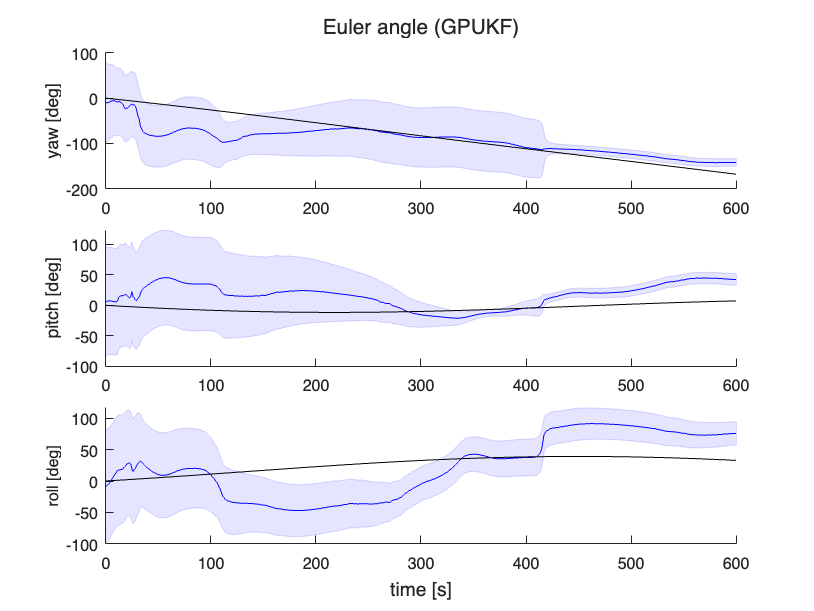

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_gu(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_gu(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "eulerAngle";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phi_gu), 'b');
hold on;
plot(t_, rad2deg(phi_true), 'k');
% hold on;
% plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold on;
% plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(theta_gu), 'b');
hold on;
plot(t_, rad2deg(theta_true), 'k');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psi_gu), 'b');
hold on;
plot(t_, rad2deg(psi_true), 'k');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

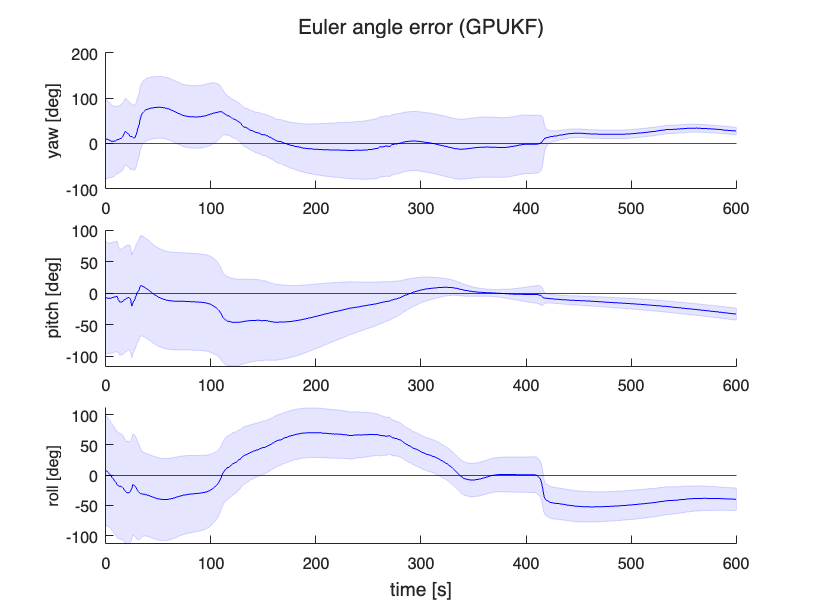



figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_gu), 'b');
% hold on;
% plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold on;
% plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

- UKF

% % UKF ------------
% filter = "UKF";
% dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "errorQuaternion";
% figure('Name', strcat(figname), 'Visible','off');
% tile = tiledlayout(4, 1);
% nexttile
% plot(t_, qe_u(:,1), 'r');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% title(strcat('error quaternion (', filter, ')'));
% nexttile;
% plot(t_, qe_u(:,2), 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_u(:, 3), 'b');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% nexttile;
% plot(t_, qe_u(:, 4), 'm');
% yline(0, '-k');
% xlim([0 t_(end,1)])
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% 
% figname = "eulerAngleError";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
% phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(phiE_u), 'r-'); 
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("yaw [deg]");
% 
% nexttile
% thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
% thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(thetaE_u), 'r');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("pitch [deg]");
% 
% nexttile
% psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
% psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% plot(t_, rad2deg(psiE_u), 'r');
% hold off;
% yline(0, '-k');
% xlim([0 t_(end,1)]);
% % ylim([-30 30]);
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle error (', filter, ')'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);

% UKF ------------
filter = "UKF";
dirName = strcat("../results/", resultDirName, "/", filter, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

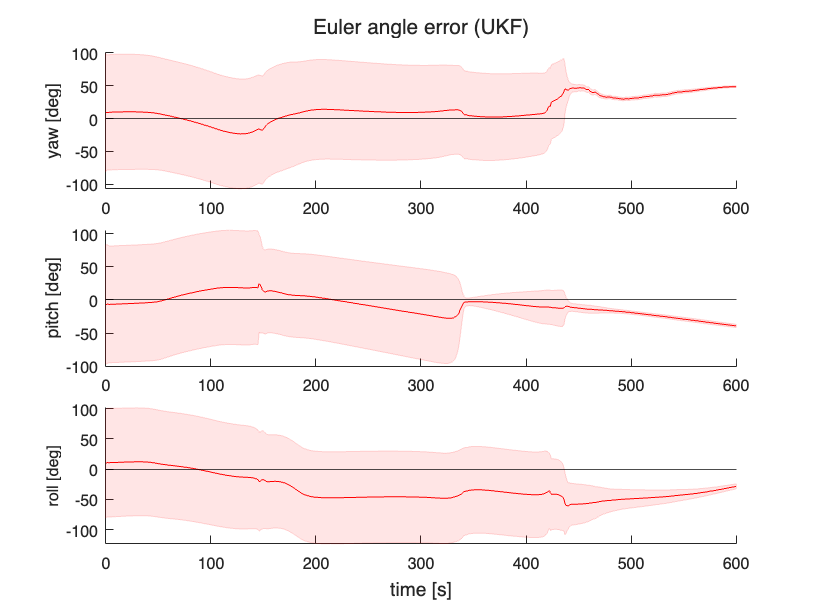

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_u(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_u(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_u), 'r-'); 
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("pitch [deg]");

nexttile
psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

- both of filters

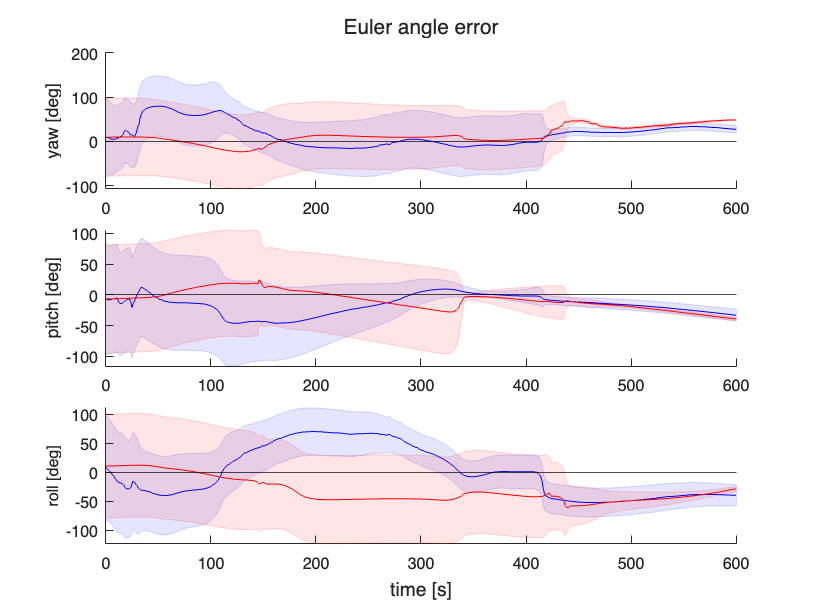

% % そのまま比較（not error）--------------
% dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% % mkdir(dirName);
% savedir = strcat(curdir, "/", dirName);
% 
% figname = "eulerAngle";
% figure('Name', figname);
% tile = tiledlayout(3,1, 'TileSpacing','Compact');
% nexttile
% phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
% phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
% phi_u_cov1 = rad2deg(phi_u + 3.*sqrt(Pdiag_u(:,1)));
% phi_u_cov2 = rad2deg(phi_u - 3.*sqrt(Pdiag_u(:,1)));
% p_u_cov = patch([t_', fliplr(t_')], [phi_u_cov1', fliplr(phi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(phi_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(phi_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(phi_true), 'k');
% hold on;
% % p_propagated = plot(t_, rad2deg(phi_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("yaw [deg]");
% legend([p_gu, p_u, p_true], {'GPUKF', 'UKF', 'true value'})
% 
% nexttile
% theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
% theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
% theta_u_cov1 = rad2deg(theta_u + 3.*sqrt(Pdiag_u(:,2)));
% theta_u_cov2 = rad2deg(theta_u - 3.*sqrt(Pdiag_u(:,2)));
% p_u_cov = patch([t_', fliplr(t_')], [theta_u_cov1', fliplr(theta_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(theta_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(theta_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(theta_true), 'k');
% hold on;
% % p_propagated = plot(t_, rad2deg(theta_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("pitch [deg]");
% 
% nexttile
% psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
% psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
% psi_u_cov1 = rad2deg(psi_u + 3.*sqrt(Pdiag_u(:,3)));
% psi_u_cov2 = rad2deg(psi_u - 3.*sqrt(Pdiag_u(:,3)));
% p_u_cov = patch([t_', fliplr(t_')], [psi_u_cov1', fliplr(psi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
% hold on;
% p_gu = plot(t_, rad2deg(psi_gu), 'b');
% hold on;
% p_u = plot(t_, rad2deg(psi_u), 'r');
% hold on;
% p_true = plot(t_, rad2deg(psi_true), 'k-');
% hold on;
% % p_propagated = plot(t_, rad2deg(psi_propagated), 'g');
% hold off;
% % yline(0, '-k');
% xlim([0 t_(end,1)])
% ylabel("roll [deg]", 'FontSize', 10);
% xlabel(tile, "time [s]")
% title(tile, strcat('Euler angle'));
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);
% 
% % 観測モデルの回帰精度を可視化 ----------
% figname = "observationModelError";
% figure('Name', figname)
% % t = tiledlayout(2,1), nexttile
% p_gu = plot(t_, ye_gu, 'b'); 
% hold on;
% 
% p_lc_gpAtti = plot(t_, ye_lc_gpAtti, 'g');
% hold on;
% p_obs = plot(t_, mAppNoise, 'k-');
% hold on;
% p_obs.Color(4) = 0.5;
% 
% p_u = plot(t_, ye_u, 'r');
% 
% legendObj = legend([p_gu, p_lc_gpAtti, p_obs, p_u], {'GP model', 'Lc model(GPUKF)', 'Observed values', 'Lc model(UKF)'})
% title('Predicted and observed light curves [-]');
% xlim([0 t_(end,1)])%, ylim([-60 60])
% ylabel("light curve")
% set(gca, 'YDir', 'reverse')
% 
% % nexttile
% % plot(t_, yee_gu, 'g');
% % yline(0, '-k');
% % xlim([0 t_(end,1)])%, ylim([-60, 60]);
% % xlabel("time [s]");
% % ylabel("litht curve error between GP model and lc model")
% 
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);

% errorで比較
dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
p_gu_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_gu), 'b');
hold on;
plot(t_, rad2deg(phiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
p_gu_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_gu), 'b');
hold on;
plot(t_, rad2deg(thetaE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
p_gu_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_gu), 'b');
hold on;
plot(t_, rad2deg(psiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


phiE_u_normMean = mean(vecnorm(phiE_u))

phiE_u_normMean = 9.9656

thetaE_u_normMean = mean(vecnorm(thetaE_u))

thetaE_u_normMean = 7.2328

psiE_u_normMean = mean(vecnorm(psiE_u))

psiE_u_normMean = 16.3447


phiE_gu_normMean = mean(vecnorm(phiE_gu))

phiE_gu_normMean = 13.5306

thetaE_gu_normMean = mean(vecnorm(thetaE_gu))

thetaE_gu_normMean = 9.7313

psiE_gu_normMean = mean(vecnorm(psiE_gu))

psiE_gu_normMean = 18.5591

そのまま比較（not error）

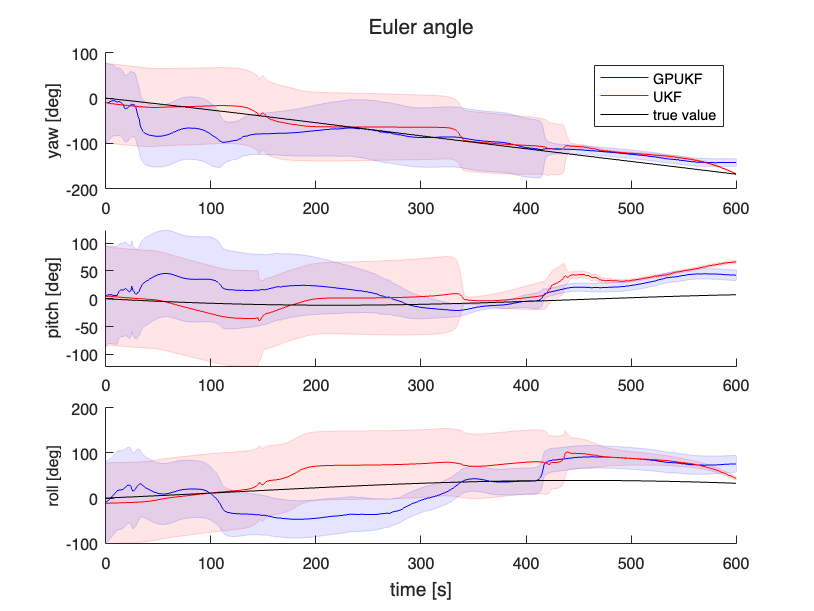

% そのまま比較（not error）--------------
dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

figname = "eulerAngle";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
phi_u_cov1 = rad2deg(phi_u + 3.*sqrt(Pdiag_u(:,1)));
phi_u_cov2 = rad2deg(phi_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phi_u_cov1', fliplr(phi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(phi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(phi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(phi_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(phi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("yaw [deg]");
legend([p_gu, p_u, p_true], {'GPUKF', 'UKF', 'true value'})

nexttile
theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
theta_u_cov1 = rad2deg(theta_u + 3.*sqrt(Pdiag_u(:,2)));
theta_u_cov2 = rad2deg(theta_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [theta_u_cov1', fliplr(theta_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(theta_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(theta_u), 'r');
hold on;
p_true = plot(t_, rad2deg(theta_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(theta_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("pitch [deg]");

nexttile
psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
psi_u_cov1 = rad2deg(psi_u + 3.*sqrt(Pdiag_u(:,3)));
psi_u_cov2 = rad2deg(psi_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psi_u_cov1', fliplr(psi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(psi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(psi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(psi_true), 'k-');
hold on;
% p_propagated = plot(t_, rad2deg(psi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

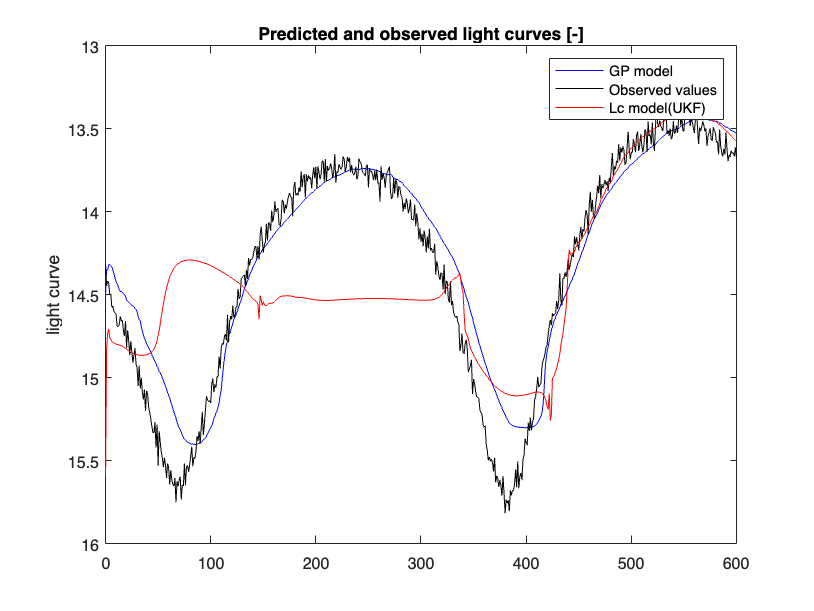


% 観測モデルの回帰精度を可視化 ----------
figname = "observationModelError";
figure('Name', figname)
% t = tiledlayout(2,1), nexttile
p_gu = plot(t_, ye_gu, 'b'); 
hold on;

% green line 消す for journal
% p_lc_gpAtti = plot(t_, ye_lc_gpAtti, 'g');
% hold on;
p_obs = plot(t_, mAppNoise, 'k-');
hold on;
p_obs.Color(4) = 0.5;

p_u = plot(t_, ye_u, 'r');

% legendObj = legend([p_gu, p_lc_gpAtti, p_obs, p_u], {'GP model', 'Lcmodel(GPUKF)', 'Observed values', 'Lc model(UKF)'});
legendObj = legend([p_gu, p_obs, p_u], {'GP model', 'Observed values', 'Lc model(UKF)'});
% legendObj = legend([p_gu, p_obs], {'GP model', 'Observed values'});
title('Predicted and observed light curves [-]');
xlim([0 t_(end,1)])%, ylim([-60 60])
ylabel("light curve")
set(gca, 'YDir', 'reverse')

% nexttile
% plot(t_, yee_gu, 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])%, ylim([-60, 60]);
% xlabel("time [s]");
% ylabel("litht curve error between GP model and lc model")

savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

export the data to csv

いつでもplotや解析ができるように

dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

fName = strcat('trueValues', '.csv');
saveName = strcat(savedir, fName);
writematrix([trueData.t_, mAppNoise, trueData.q, phi_true, theta_true, psi_true, trueData.w, trueData.r, trueData.v, trueData.obsECI, trueData.sunPosI, trueData.jdHistory], saveName); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

fName = strcat('estimatedValues_GPUKF', '.csv');
saveName = strcat(savedir, fName);
writematrix([t_, ye_gu, qGlobal_gu, phi_gu, theta_gu, psi_gu, Pdiag_gu, wGlobal_gu], saveName); 

fName = strcat('estimatedValues_UKF', '.csv');
saveName = strcat(savedir, fName);
writematrix([t_, ye_u, qGlobal_u, phi_u, theta_u, psi_u, Pdiag_u, wGlobal_u], saveName); 

fName = strcat('errors_GPUKF', '.csv');
saveName = strcat(savedir, fName);
writematrix([t_, ye_gu - mAppNoise, qe_gu, phiE_gu, thetaE_gu, psiE_gu, Pdiag_gu], saveName); 

fName = strcat('errors_UKF', '.csv');
saveName = strcat(savedir, fName);
writematrix([t_, ye_u - mAppNoise, qe_u, phiE_u, thetaE_u, psiE_u, Pdiag_u], saveName); 

RMSE (Root Mean Square Error)

tStartIndex_rmse = 1; % from start
tEndIndex_rmse = size(t_, 1); % to End



phi_gu_rmse = rad2deg(rmse(phi_gu, phi_true)); % [deg]
theta_gu_rmse = rad2deg(rmse(theta_gu, theta_true)); % [deg]
psi_gu_rmse = rad2deg(rmse(psi_gu, psi_true)); % [deg]
ye_gu_rmse = rmse(ye_gu, mAppNoise);

phi_u_rmse = rad2deg(rmse(phi_u, phi_true)); % [deg]
theta_u_rmse = rad2deg(rmse(theta_u, theta_true)); % [deg]
psi_u_rmse = rad2deg(rmse(psi_u, psi_true)); % [deg]
ye_u_rmse = rmse(ye_u, mAppNoise);

fprintf("the RMSE of the phi (GPUKF): %f [deg] \n", phi_gu_rmse);

the RMSE of the phi (GPUKF): 28.452012 [deg] 


fprintf("the RMSE of the theta (GPUKF): %f [deg] \n", theta_gu_rmse);

the RMSE of the theta (GPUKF): 27.098542 [deg] 


fprintf("the RMSE of the psi (GPUKF): %f [deg] \n", psi_gu_rmse);

the RMSE of the psi (GPUKF): 42.964063 [deg] 


fprintf("the RMSE of the mApp (GPUKF): %f [-] \n", ye_gu_rmse);

the RMSE of the mApp (GPUKF): 0.210867 [-] 



fprintf("the RMSE of the phi (UKF): %f [deg] \n", phi_u_rmse);

the RMSE of the phi (UKF): 12.988889 [deg] 


fprintf("the RMSE of the theta (UKF): %f [deg] \n", theta_u_rmse);

the RMSE of the theta (UKF): 25.425034 [deg] 


fprintf("the RMSE of the psi (UKF): %f [deg] \n", psi_u_rmse);

the RMSE of the psi (UKF): 37.448632 [deg] 


fprintf("the RMSE of the mApp (UKF): %f [-] \n", ye_u_rmse);

the RMSE of the mApp (UKF): 0.523964 [-] 



% export to txt
fName = 'RMSE_calcTime.dat';
saveName = strcat(savedir, fName);
RMSE_calcTime_cell = {'phi_GPUKF', phi_gu_rmse, '[deg]';
            'theta_GPUKF', theta_gu_rmse, '[deg]';
            'psi_GPUKF', psi_gu_rmse, '[deg]';
            'mApp_GPUKF', ye_gu_rmse, '[-]';
            '--', '--', '--';
            'phi_UKF', phi_u_rmse, '[deg]';
            'theta_UKF', theta_u_rmse, '[deg]';
            'psi_UKF', psi_u_rmse, '[deg]';
            'mApp_UKF', ye_u_rmse, '[-]';
            '--', '--', '--';
            'calculation time (cmp_GPUKF_UKF)', tEnd_GPUKF_UKF, '[min]';
            };
writecell(RMSE_calcTime_cell, saveName);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))

ans = "calculation time [min] : 1.2881"

strcat("calculation time [hours] : ", num2str(tEnd/60))

ans = "calculation time [hours] : 0.021468"